**FIT3081 Assignment 2 **

**Iris Detection and Recognition**

**By: Chong Chiu Gin, Lee Sher Wyn, Ng Wei Vern**

This file is for showing output for image in each section. 

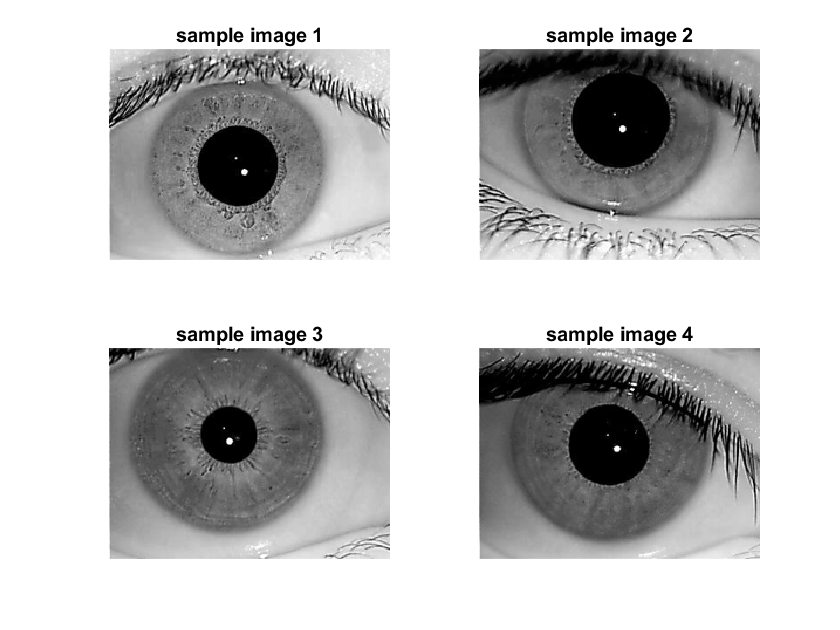

% this code file is to run and show output images for each section of our
% project methodology
% NOTE : names of image files has to be hardcoded into the code before
% running the program


% reading images 
% image pre-processing
I1 = rgb2gray(imread("001_01.bmp"));
I1 = imresize(I1,.75);
I2 = rgb2gray(imread("002_01.bmp"));
I2 = imresize(I2,.75);
I3 = rgb2gray(imread("003_01.bmp"));
I3 = imresize(I3,.75);
I4 = rgb2gray(imread("004_01.bmp"));
I4 = imresize(I4,.75);

figure, subplot(2,2,1), imshow(I1); title("sample image 1");
subplot(2,2,2), imshow(I2); title("sample image 2");
subplot(2,2,3), imshow(I3); title("sample image 3");
subplot(2,2,4), imshow(I4); title("sample image 4");

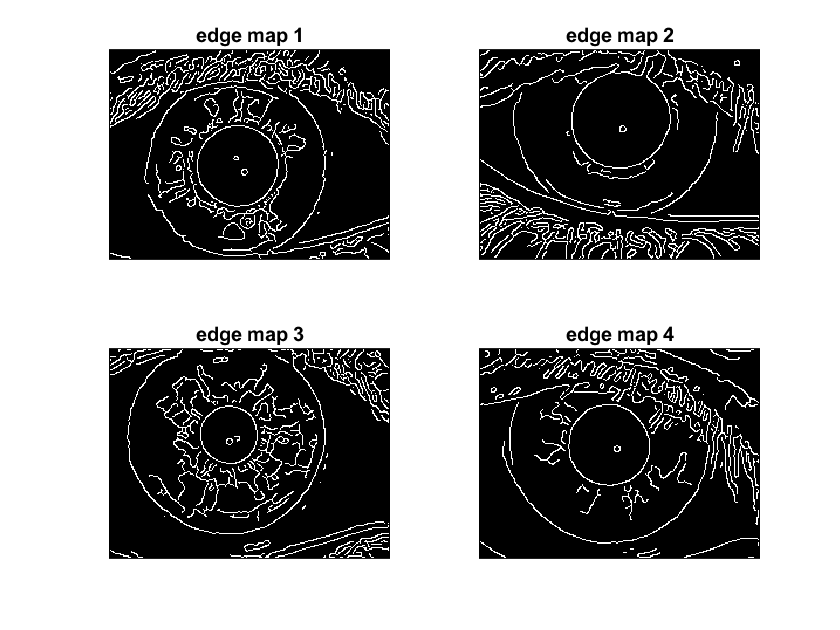

%apply median filter to remove 'salt and pepper' noise and 
% then apply canny so edge map looks neater
I1 = medfilt2(I1);
I2 = medfilt2(I2);
I3 = medfilt2(I3);
I4 = medfilt2(I4);
canny1 = edge(I1, 'canny');
canny2 = edge(I2, 'canny');
canny3 = edge(I3, 'canny');
canny4 = edge(I4, 'canny');

figure, subplot(2,2,1), imshow(canny1); title("edge map 1");
subplot(2,2,2), imshow(canny2); title("edge map 2");
subplot(2,2,3), imshow(canny3); title("edge map 3");
subplot(2,2,4), imshow(canny4); title("edge map 4");

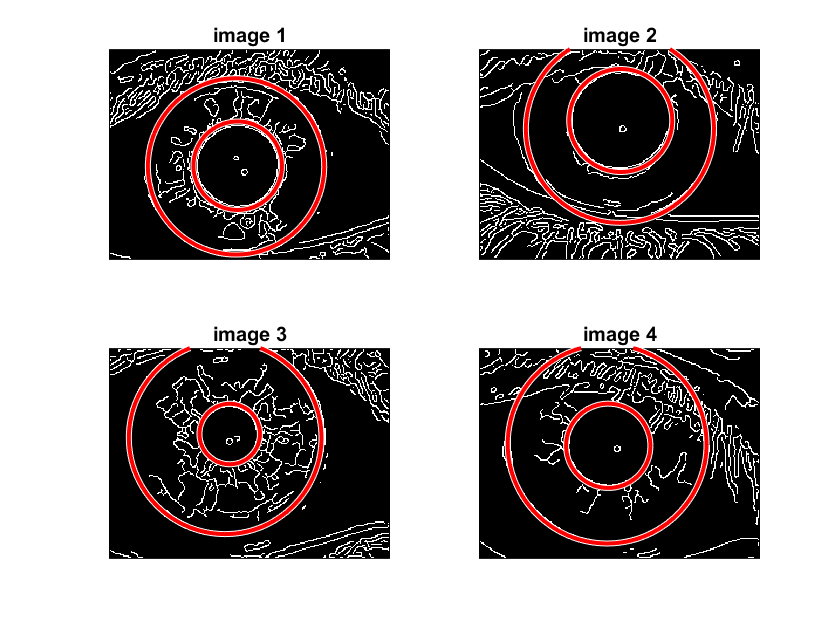

% detect circles with hough transform

%image 1
[centers1_pupil, radii1_pupil] = imfindcircles(canny1, [20 55], 'Sensitivity',0.90);
[centers1_iris, radii1_iris] = imfindcircles(canny1, [60 150], 'Sensitivity',0.95);
figure, subplot(2,2,1), imshow(canny1); viscircles(centers1_pupil, radii1_pupil, 'EdgeColor', 'r'); viscircles(centers1_iris, radii1_iris, 'EdgeColor', 'r'); title("image 1");

%image 2
[centers2_pupil, radii2_pupil] = imfindcircles(canny2, [20 55], 'Sensitivity',0.90);
[centers2_iris, radii2_iris] = imfindcircles(canny2, [60 150], 'Sensitivity',0.95);
subplot(2,2,2), imshow(canny2); viscircles(centers2_pupil, radii2_pupil, 'EdgeColor', 'r'); viscircles(centers2_iris, radii2_iris, 'EdgeColor', 'r'); title("image 2");

%image 3
[centers3_pupil, radii3_pupil] = imfindcircles(canny3, [20 55], 'Sensitivity',0.90);
[centers3_iris, radii3_iris] = imfindcircles(canny3, [60 150], 'Sensitivity',0.95);
subplot(2,2,3), imshow(canny3); viscircles(centers3_pupil, radii3_pupil, 'EdgeColor', 'r'); viscircles(centers3_iris, radii3_iris, 'EdgeColor', 'r'); title("image 3");

%image 4
[centers4_pupil, radii4_pupil] = imfindcircles(canny4, [20 55], 'Sensitivity',0.90);
[centers4_iris, radii4_iris] = imfindcircles(canny4, [60 150], 'Sensitivity',0.95);
subplot(2,2,4), imshow(canny4); viscircles(centers4_pupil, radii4_pupil, 'EdgeColor', 'r'); viscircles(centers4_iris, radii4_iris, 'EdgeColor', 'r'); title("image 4");

% setting values for image 1
xIris = centers1_iris(1);
yIris = centers1_iris(2);
rIris = radii1_iris;
xPupil = centers1_pupil(1);
yPupil = centers1_pupil(2);
rPupil = radii1_pupil;

% setting values for image 2
xIris2 = centers2_iris(1);
yIris2 = centers2_iris(2);
rIris2 = radii2_iris;
xPupil2 = centers2_pupil(1);
yPupil2 = centers2_pupil(2);
rPupil2 = radii2_pupil;

% setting values for image 3
xIris3 = centers3_iris(1);
yIris3 = centers3_iris(2);
rIris3 = radii3_iris;
xPupil3 = centers3_pupil(1);
yPupil3 = centers3_pupil(2);
rPupil3 = radii3_pupil;

% setting values for image 4
xIris4 = centers4_iris(1);
yIris4 = centers4_iris(2);
rIris4 = radii4_iris;
xPupil4 = centers4_pupil(1);
yPupil4 = centers4_pupil(2);
rPupil4 = radii4_pupil;

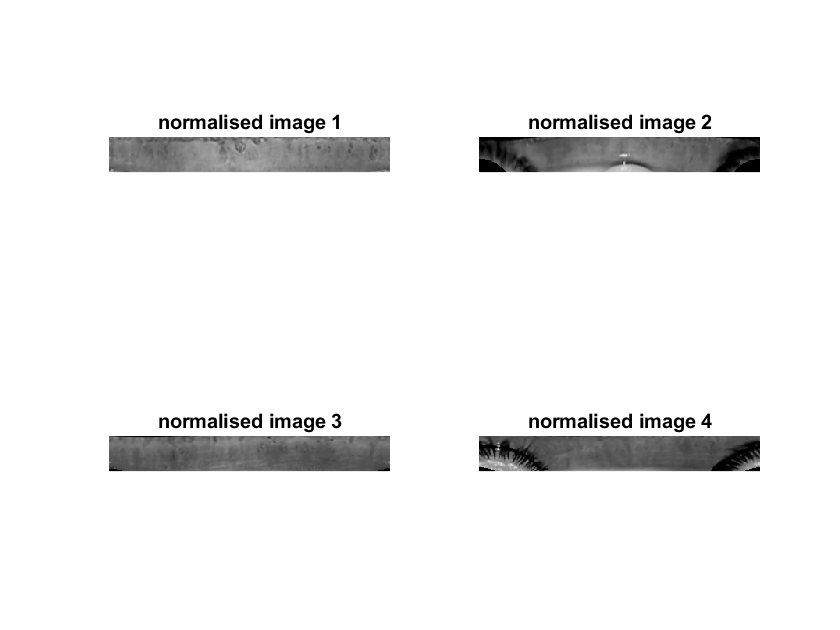

%normalization
n1 = normalisation(I1, xIris, yIris, rIris, xPupil, yPupil, rPupil);
n2 = normalisation(I2, xIris2, yIris2, rIris2, xPupil2, yPupil2, rPupil2);
n3 = normalisation(I3, xIris3, yIris3, rIris3, xPupil3, yPupil3, rPupil3);
n4 = normalisation(I4, xIris4, yIris4, rIris4, xPupil4, yPupil4, rPupil4);
figure, subplot(2,2,1), imshow(n1); title("normalised image 1");
subplot(2,2,2), imshow(n2); title("normalised image 2");
subplot(2,2,3), imshow(n3); title("normalised image 3");
subplot(2,2,4), imshow(n4); title("normalised image 4");

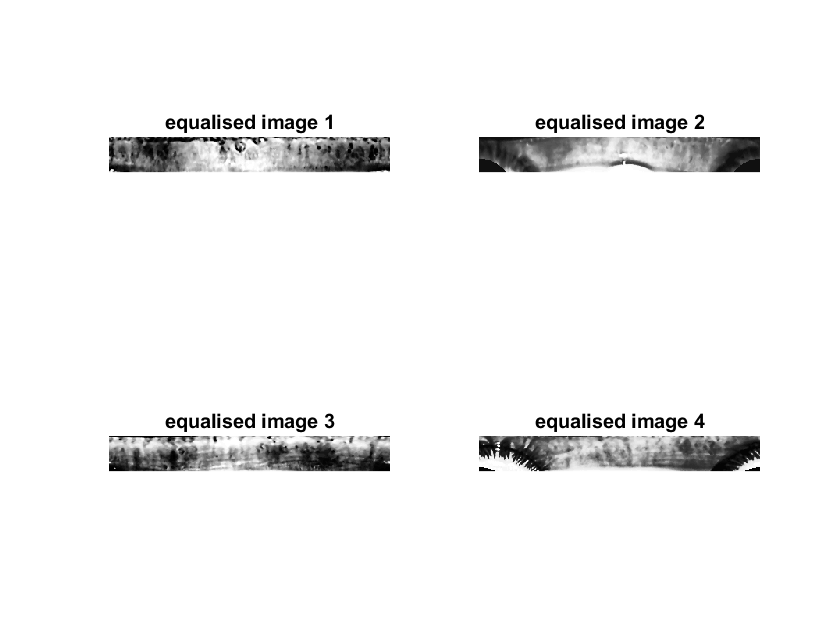

% historgram equalized the normalised image to increase contrast between pixels 
equalise1 = histeq(n1);
equalise2 = histeq(n2);
equalise3 = histeq(n3);
equalise4 = histeq(n4);

figure, subplot(2,2,1), imshow(equalise1); title("equalised image 1");
subplot(2,2,2), imshow(equalise2); title("equalised image 2");
subplot(2,2,3), imshow(equalise3); title("equalised image 3");
subplot(2,2,4), imshow(equalise4); title("equalised image 4");

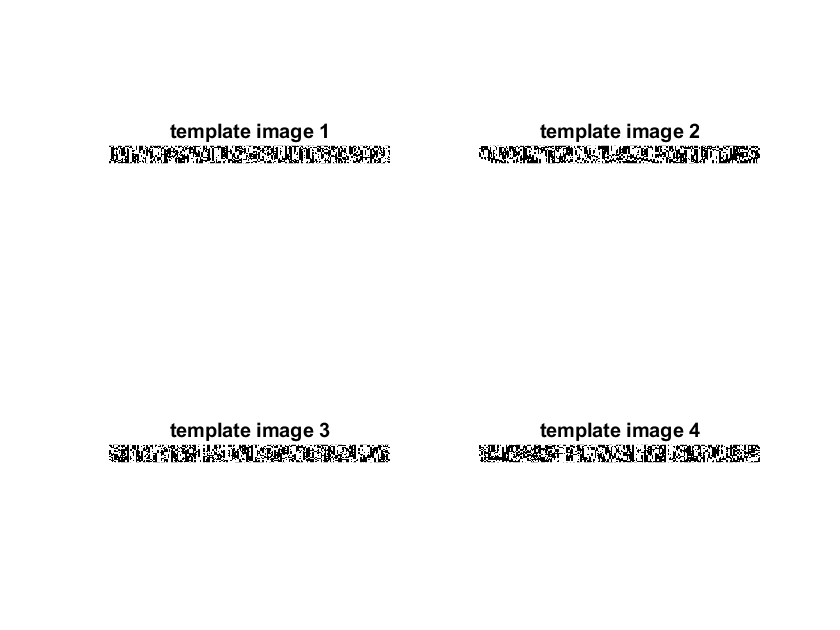

% feature extraction with log gabor filter
[template1] = logGaborFilter(equalise1);
[template2] = logGaborFilter(equalise2);
[template3] = logGaborFilter(equalise3);
[template4] = logGaborFilter(equalise4);
figure, subplot(2,2,1), imshow(template1); title("template image 1");
subplot(2,2,2), imshow(template2); title("template image 2");
subplot(2,2,3), imshow(template3); title("template image 3");
subplot(2,2,4), imshow(template4); title("template image 4");

%hamming distance
% testing every pairwise 

hd1_2 = hammingDistance(template1,template2);
hd1_3 = hammingDistance(template1,template3);
hd1_4 = hammingDistance(template1,template4);
hd2_3 = hammingDistance(template2,template3);
hd2_4 = hammingDistance(template2,template4);
hd3_4 = hammingDistance(template3,template4);

function normalisedImage = normalisation(image, xIris, yIris, rIris, xPupil, yPupil, rPupil)
    
    offsetX = yIris - yPupil;
    offsetY = xIris - xPupil;
    
    angleSize = 360; % these values are basically the size of the normalised image. setting them smaller will go faster due to less pixel processing
    radiusSize = 45; 
    
    normalisedImage = zeros(radiusSize, angleSize);
    for t=1:angleSize
        radiusColumn = zeros(radiusSize,1);
        for r=1:radiusSize
            currAngle = (t-1)*2*pi/angleSize + pi;
            
            % calculates distance between edge of iris and edge of pupil for every angle and radius
            % based on daugman's formula
            a = offsetX^2 + offsetY^2;
            b = cos(pi-atan(offsetY/offsetX)-angleSize);
            dist = sqrt(a)*b + sqrt(rIris^2 - a + a*b^2);

            % get the cordinate values for interpolation
            ro = (dist - rPupil)*r/radiusSize + rPupil;
            x = xIris - (ro)*sin(currAngle);
            y = yIris + (ro)*cos(currAngle);

            % interpolation to determine intensity values of normalised image
            radiusColumn(r,1) = interp2(double(image), x, y, "linear");
    
        end
        normalisedImage(:,t) = radiusColumn;
    end
    normalisedImage = uint8(normalisedImage);
end


function template = logGaborFilter(normalised_image)

    [rows,cols] = size(normalised_image);   
    
    % initialisation of filter array and result array
    logGabor = zeros(1,cols);
    result = zeros(rows,cols);
    
    % initialise values to calculate log gabor filter
    radius =  (0:fix(cols/2))/fix(cols/2)/2;  
    radius(1) = 1;
    fo = 1/18;    % Centre frequency of filter = 1/wavelength where wavelength initialised to 18
    sigmaOfFrequency = 0.5;
    
    % calculate the filter
    logGabor(1:cols/2+1) = exp((-(log(radius/fo)).^2) / (2 * log(sigmaOfFrequency)^2));  
    logGabor(1) = 0;  
    
    % for each row of the input image, perform convolution
    for r = 1:rows
        signal = normalised_image(r,1:cols);
        imagefft = fft(signal); %give frequency information of the signal 
        result(r,:) = ifft(imagefft .* logGabor); %inverse back
    end

    template = zeros(size(normalised_image,1), cols*2);
    h = 1:size(normalised_image,1);
    
    % splitting real and imaginary for complex number
    realN = real(result) > 0;
    imaginaryN = imag(result) > 0;
    
    % construct the biometric template using phase quantisation of real and
    % imaginary component
    for i=0:(cols-1)
        j = double(2*(i));
        template(h,j+(2)-1) = realN(h, i+1);
        template(h,j+(2)) = imaginaryN(h,i+1);
    end

end

function dist = hammingDistance(gaborTemplate1, gaborTemplate2)
    % preparing both templates to be compared
    template1 = logical(gaborTemplate1);
    template2 = logical(gaborTemplate2);
    
    % calculate total number of bits in template
    totalBits = size(template1,1)*size(template1,2);
    
    % perform XOR of both template
    templateXOR = xor(template1,template2);
    
    % obtain number of differet bits in both template
    difference = sum(templateXOR==1);
    differenceBits = sum(difference);
    
    % hamming distance = difference / total
    dist = differenceBits/totalBits;
end